## Ulog informations

data = ulogreader("log_2_2023-3-27-21-56-34.ulg")

data =   ulogreader with properties:

            FileName: "log_2_2023-3-27-21-56-34.ulg"
           StartTime: 00:00:00.164000
             EndTime: 00:06:28.144000
     AvailableTopics: [161×5 table]
    DropoutIntervals: [0×2 duration]


start_time = data.StartTime;
end_time = data.EndTime;
msg = readTopicMsgs(data)

msg = 161×6 table
          TopicNames           InstanceID    StartTimestamp      LastTimestamp        TopicMessages         MsgFormat  
    _______________________    __________    _______________    _______________    ____________________    ____________

    "actuator_armed"               0         00:00:00.032000    00:06:27.648000    {  773×8  timetable}    { 9×3 table}
    "actuator_controls_0"          0         00:00:07.220000    00:06:28.144000    {69433×2  timetable}    { 3×3 table}
    "actuator_controls_3"          0         00:00:00.024000    00:06:28.068000    { 3036×2  timetable}    { 3×3 table}
    "actuator_outputs"             0         00:00:07.220000    00:06:28.120000    { 3811×2  timetable}    { 4×3 table}
    "airspeed"                     0         00:00:00.096

%systeminfo = readSystemInformation(data)
%params = readParameters(data)
%loggedoutput = readLoggedOutput(data)
plotter = flightLogSignalMapping("ulog");
%info(plotter,"Signal")
%show(plotter,data)

## EXtracting relevant information

%extract actuator control data
actuator_data = data.readTopicMsgs('TopicNames',"actuator_controls_0",'InstanceID',{0});
actuator = actuator_data.TopicMessages{1};
roll_in = timetable(actuator.timestamp,actuator.control(:,1),'VariableNames',{'roll_in'}); 
pitch_in = timetable(actuator.timestamp,actuator.control(:,2),'VariableNames',{'pitch_in'}); 
yaw_in = timetable(actuator.timestamp,actuator.control(:,3),'VariableNames',{'yaw_in'}); 
throttle_in = timetable(actuator.timestamp,actuator.control(:,4),'VariableNames',{'throttle_in'}); 
flaps_in = timetable(actuator.timestamp,actuator.control(:,5),'VariableNames',{'flap_in'}); 

%extract RC in data
rc_data = data.readTopicMsgs('TopicNames',"input_rc",'InstanceID',{0});
rc = rc_data.TopicMessages{1};
roll_rc = timetable(rc.timestamp,(rc.values(:,1)-1500)/500,'VariableNames',{'roll_rc'}); 
pitch_rc = timetable(rc.timestamp,(rc.values(:,2)-1500)/500,'VariableNames',{'pitch_rc'}); 
yaw_rc = timetable(rc.timestamp,(rc.values(:,3)-1500)/500,'VariableNames',{'yaw_rc'}); 
throttle_rc = timetable(rc.timestamp,(rc.values(:,4)-1000)/500,'VariableNames',{'throttle_rc'}); 

%extract sensor data
sensor_data = data.readTopicMsgs('TopicNames',"sensor_combined",'InstanceID',{0});
sensor = sensor_data.TopicMessages{1};
GyroX = timetable(sensor.timestamp,sensor.gyro_rad(:,1),'VariableNames',{'GyroX'}); 
GyroY = timetable(sensor.timestamp,sensor.gyro_rad(:,2),'VariableNames',{'GyroY'}); 
GyroZ = timetable(sensor.timestamp,sensor.gyro_rad(:,3),'VariableNames',{'GyroZ'}); 
AccelX = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,1),'VariableNames',{'AccelX'}); 
AccelY = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,2),'VariableNames',{'AccelY'}); 
AccelZ = timetable(sensor.timestamp,sensor.accelerometer_m_s2(:,3),'VariableNames',{'AccelZ'}); 

%extract angular acceleration
angular_acc_data = data.readTopicMsgs('TopicNames',"vehicle_angular_acceleration",'InstanceID',{0});
angular_acc = angular_acc_data.TopicMessages{1};
pd=timetable(angular_acc.timestamp,angular_acc.xyz(:,1), 'VariableNames',{'pd'}); 
qd=timetable(angular_acc.timestamp,angular_acc.xyz(:,2), 'VariableNames',{'qd'});     
rd=timetable(angular_acc.timestamp,angular_acc.xyz(:,3), 'VariableNames',{'rd'}); 

%extract global position
position_data = data.readTopicMsgs('TopicNames',"vehicle_global_position",'InstanceID',{0});
position = position_data.TopicMessages{1};
lat=timetable(position.timestamp,position.lat, 'VariableNames',{'lat'});
lon=timetable(position.timestamp,position.lon, 'VariableNames',{'lon'});
alt=timetable(position.timestamp,position.alt, 'VariableNames',{'alt'});

%extract experiment
experiment_data = data.readTopicMsgs('TopicNames',"experiment",'InstanceID',{0});
experiment = experiment_data.TopicMessages{1};
flag=timetable(experiment.timestamp,experiment.experiment_running, 'VariableNames',{'flag'});
step=timetable(experiment.timestamp,experiment.injection_input(:,1), 'VariableNames',{'step'});
doublet=timetable(experiment.timestamp,experiment.injection_input(:,2), 'VariableNames',{'doublet'});
sine=timetable(experiment.timestamp,experiment.injection_input(:,3), 'VariableNames',{'sine'});
throttle=timetable(experiment.timestamp,experiment.injection_output(:,1), 'VariableNames',{'throttle'});
elevator=timetable(experiment.timestamp,experiment.injection_output(:,2), 'VariableNames',{'elevator'});
mag=timetable(experiment.timestamp,experiment.input_parameter(:,1), 'VariableNames',{'magnitude'});
durations=timetable(experiment.timestamp,experiment.input_parameter(:,2), 'VariableNames',{'durations'});
fstart=timetable(experiment.timestamp,experiment.input_parameter(:,3), 'VariableNames',{'fstart'});
fend=timetable(experiment.timestamp,experiment.input_parameter(:,4), 'VariableNames',{'fend'});

%extract airspeed
airspeed_data = data.readTopicMsgs('TopicNames',"airspeed_validated",'InstanceID',{0});
airspeed = airspeed_data.TopicMessages{1};
ind_airspeed=timetable(airspeed.timestamp,airspeed.indicated_airspeed_m_s, 'VariableNames',{'indicated_airspeed'});
cal_airspeed=timetable(airspeed.timestamp,airspeed.calibrated_airspeed_m_s, 'VariableNames',{'calibrated_airspeed'});
true_airspeed=timetable(airspeed.timestamp,airspeed.true_airspeed_m_s, 'VariableNames',{'true_airspeed'});

%extract angular velocity
angular_vel_data = data.readTopicMsgs('TopicNames',"vehicle_angular_velocity",'InstanceID',{0});
angular_vel = angular_acc_data.TopicMessages{1};
p=timetable(angular_vel.timestamp,angular_vel.xyz(:,1), 'VariableNames',{'p'}); 
q=timetable(angular_vel.timestamp,angular_vel.xyz(:,2), 'VariableNames',{'q'});     
r=timetable(angular_vel.timestamp,angular_vel.xyz(:,3), 'VariableNames',{'r'}); 

%extract attitude
att_data = data.readTopicMsgs('TopicNames',"vehicle_attitude",'InstanceID',{0});
att=att_data.TopicMessages{1};
q1=timetable(att.timestamp,att.q(:,1), 'VariableNames',{'q1'});     
q2=timetable(att.timestamp,att.q(:,2), 'VariableNames',{'q2'});  
q3=timetable(att.timestamp,att.q(:,3), 'VariableNames',{'q3'});  
q4=timetable(att.timestamp,att.q(:,4), 'VariableNames',{'q4'});  

%extract estimated wind data
wind_data = data.readTopicMsgs('TopicNames',"wind",'InstanceID',{0});
wind = wind_data.TopicMessages{1};
windNorth=wind.windspeed_north(:,1);
windEast=wind.windspeed_east(:,1);
wn=timetable(wind.timestamp,windNorth, 'VariableNames',{'wn'}); 
we=timetable(wind.timestamp,windEast, 'VariableNames',{'we'});     %wind disturbance data

% Extract battery data.
battery_data = data.readTopicMsgs('TopicNames',"battery_status",'InstanceID',{0});
battery = battery_data.TopicMessages{1};
Voltage = timetable(battery.timestamp,battery.voltage_cell_v(:,1),'VariableNames',{'Voltage_1'});
Capacity = timetable(battery.timestamp,battery.remaining_capacity,'VariableNames',{'RemainingCapacity'});

## Synchronise 

%synchronization
% Combine all tables into one
step = unique(step);
doublet = unique(doublet); 
sine = unique(sine);
throttle = unique(throttle); 
elevator = unique(elevator);
sync_data = synchronize(roll_in, pitch_in, yaw_in, throttle_in, flaps_in,roll_rc, pitch_rc, yaw_rc, throttle_rc, GyroX, GyroY, GyroZ,Voltage,Capacity, AccelX, AccelY, AccelZ, pd, qd, rd, lat, lon, alt, step, doublet, sine, throttle, elevator, ind_airspeed, cal_airspeed, true_airspeed, p, q, r, q1, q2, q3, q4, wn, we,'union','linear');

% calculate wind speed
windspeed = sqrt(sync_data.wn.^2 + sync_data.we.^2);
windSpeed=timetable(sync_data.Time,windspeed, 'VariableNames',{'windSpeed'});  
% Calculate angle of attack
alpha = atan((sync_data.indicated_airspeed - windspeed) ./ sync_data.true_airspeed);
alpha = timetable(sync_data.Time,alpha,'VariableNames',{'alpha'});

% remove NaN values and save as CSV file
sync_data = synchronize(roll_in, pitch_in, yaw_in, throttle_in, flaps_in,roll_rc, pitch_rc, yaw_rc, throttle_rc, GyroX, GyroY, GyroZ,Voltage,Capacity,  AccelX, AccelY, AccelZ, pd, qd, rd, lat, lon, alt, step, doublet, sine, throttle, elevator, ind_airspeed, cal_airspeed, true_airspeed, p, q, r, q1, q2, q3, q4, wn, we,alpha,windSpeed,'union','linear');
sync_data = rmmissing(sync_data);
writetimetable(sync_data,'data.csv');
[n1 n2] = size(sync_data)

n1 = 93120

n2 = 42

## Ploting the data

roll_in = timetable(sync_data.Time,sync_data.roll_in,'VariableNames',{'roll_in'}); 
pitch_in = timetable(sync_data.Time,sync_data.pitch_in,'VariableNames',{'pitch_in'}); 
yaw_in = timetable(sync_data.Time,sync_data.yaw_in,'VariableNames',{'yaw_in'}); 
throttle_in = timetable(sync_data.Time,sync_data.throttle_in,'VariableNames',{'throttle_in'}); 
roll_rc = timetable(sync_data.Time,sync_data.roll_in,'VariableNames',{'roll_rc'}); 
pitch_rc = timetable(sync_data.Time,sync_data.pitch_rc,'VariableNames',{'pitch_rc'}); 
yaw_rc = timetable(sync_data.Time,sync_data.yaw_rc,'VariableNames',{'yaw_rc'}); 
throttle_rc = timetable(sync_data.Time,sync_data.throttle_rc,'VariableNames',{'throttle_rc'}); 
flaps_in = timetable(sync_data.Time,sync_data.flap_in,'VariableNames',{'flap_in'}); 
GyroX = timetable(sync_data.Time,sync_data.GyroX,'VariableNames',{'GyroX'}); 
GyroY = timetable(sync_data.Time,sync_data.GyroY,'VariableNames',{'GyroY'}); 
GyroZ = timetable(sync_data.Time,sync_data.GyroZ,'VariableNames',{'GyroZ'}); 
AccelX = timetable(sync_data.Time,sync_data.AccelX,'VariableNames',{'AccelX'}); 
AccelY = timetable(sync_data.Time,sync_data.AccelY,'VariableNames',{'AccelY'}); 
AccelZ = timetable(sync_data.Time,sync_data.AccelZ,'VariableNames',{'AccelZ'}); 
pd=timetable(sync_data.Time,sync_data.pd , 'VariableNames',{'pd'}); 
qd=timetable(sync_data.Time,sync_data.qd, 'VariableNames',{'qd'});     
rd=timetable(sync_data.Time,sync_data.rd, 'VariableNames',{'rd'}); 
lat=timetable(sync_data.Time,sync_data.lat, 'VariableNames',{'lat'});
lon=timetable(sync_data.Time,sync_data.lon, 'VariableNames',{'lon'});
alt=timetable(sync_data.Time,sync_data.alt, 'VariableNames',{'alt'});
step=timetable(sync_data.Time,sync_data.step, 'VariableNames',{'step'});
doublet=timetable(sync_data.Time,sync_data.doublet, 'VariableNames',{'doublet'});
sine=timetable(sync_data.Time,sync_data.sine, 'VariableNames',{'sine'});
throttle=timetable(sync_data.Time,sync_data.throttle, 'VariableNames',{'throttle'});
elevator=timetable(sync_data.Time,sync_data.elevator, 'VariableNames',{'elevator'});
ind_airspeed=timetable(sync_data.Time,sync_data.indicated_airspeed, 'VariableNames',{'indicated_airspeed'});
cal_airspeed=timetable(sync_data.Time,sync_data.calibrated_airspeed, 'VariableNames',{'calibrated_airspeed'});
true_airspeed=timetable(sync_data.Time,sync_data.true_airspeed, 'VariableNames',{'true_airspeed'});
p=timetable(sync_data.Time,sync_data.p, 'VariableNames',{'p'}); 
q=timetable(sync_data.Time,sync_data.GyroY,'VariableNames',{'q'});     
r=timetable(sync_data.Time,sync_data.r, 'VariableNames',{'r'}); 
q1=timetable(sync_data.Time,sync_data.q1, 'VariableNames',{'q1'});     
q2=timetable(sync_data.Time,sync_data.q2, 'VariableNames',{'q2'});  
q3=timetable(sync_data.Time,sync_data.q3, 'VariableNames',{'q3'});  
q4=timetable(sync_data.Time,sync_data.q4, 'VariableNames',{'q4'}); 
wn=timetable(sync_data.Time,sync_data.wn, 'VariableNames',{'wn'}); 
we=timetable(sync_data.Time,sync_data.we, 'VariableNames',{'we'});    
Voltage = timetable(sync_data.Time,sync_data.Voltage_1,'VariableNames',{'Voltage_1'});
Capacity = timetable(sync_data.Time,sync_data.RemainingCapacity,'VariableNames',{'RemainingCapacity'});
alpha = timetable(sync_data.Time,sync_data.alpha,'VariableNames',{'alpha'});
windSpeed=timetable(sync_data.Time,sync_data.windSpeed, 'VariableNames',{'windSpeed'});  

## customData structure

customData.Gyro = [GyroX GyroY GyroZ];
customData.Accel = [AccelX AccelY AccelZ];
customData.control  = [roll_in pitch_in yaw_in throttle_in flaps_in];
customData.Angular_acc = [pd qd rd];
customData.rc  = [roll_rc pitch_rc yaw_rc throttle_rc];
customData.position = [lat lon alt];
customData.experiment = [step doublet sine throttle elevator];
customData.airspeed = [ind_airspeed cal_airspeed true_airspeed];
customData.Angular_vel = [p q r];
customData.wind = [wn we windSpeed];
customData.attitude = [q1 q2 q3 q4];
customData.battery = [Voltage Capacity];
customData.Alpha = [alpha];
Ts = seconds(seconds(end_time -start_time)/n1)

Ts = duration
   0.0041665 sec


## Plots

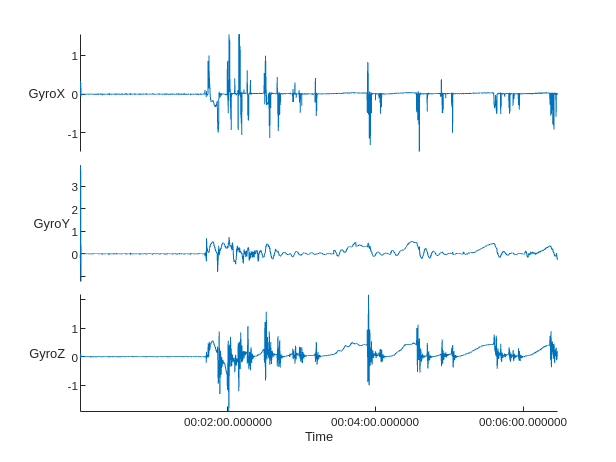

stackedplot(customData.Gyro);

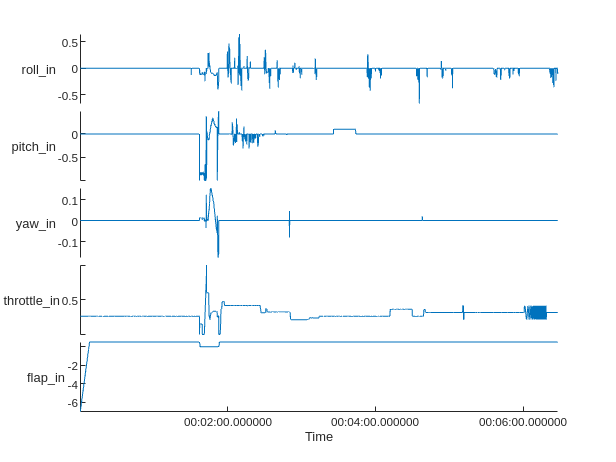

% stackedplot(customData.Accel);
stackedplot(customData.control);

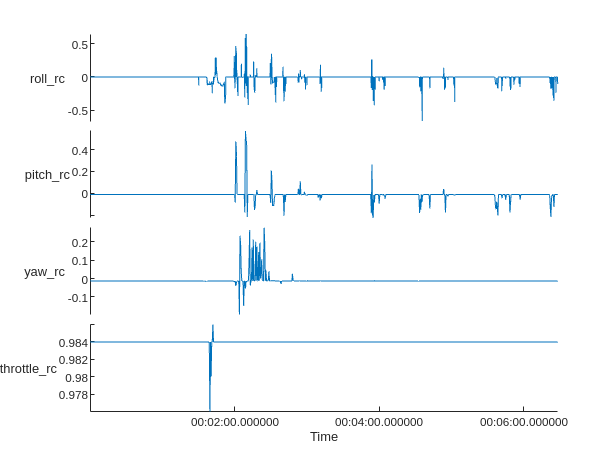

stackedplot(customData.rc);

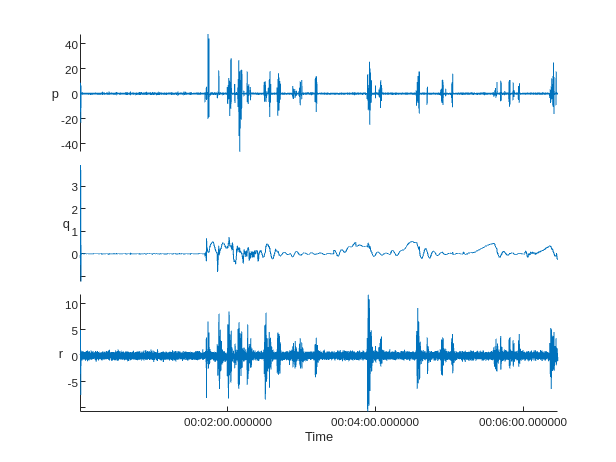

%stackedplot(customData.Angular_acc);
% stackedplot(customData.position);
% geoplot(customData.position.lat, customData.position.lon)
% stackedplot(customData.experiment);
% stackedplot(customData.airspeed);
 stackedplot(customData.Angular_vel);

% stackedplot(customData.wind);
% stackedplot(customData.attitude);
% stackedplot(customData.battery);
% stackedplot(customData.Alpha);